# This script generates Figures 14 and 15

Found 0 exceedences: Estimated nu = 8 and epsilon = 0.090909


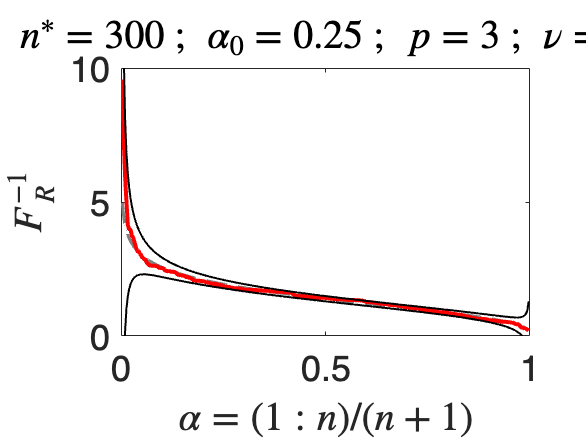

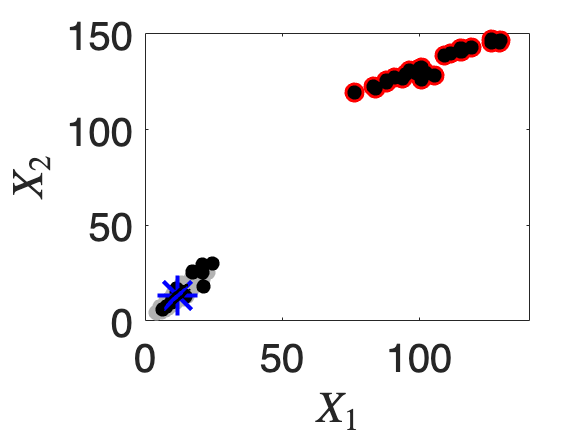

% location of the two real datasets
ds_path = './datasets';
dsfile1 = 'Grass_contaminated.prn';
dsfile2 = 'Returns_1991_1992_CanUK_contaminated.prn';

% Apply algorithm 3 to DS1: Grass
dsfile = [ds_path filesep dsfile1];
X1     = load(dsfile);
n1     = size(X1,1);
Xlabels1 = zeros(n1,1);
Xlabels1(n1-30+1:end) = 1;
alpha01 = 0.25;
[Grass_epsilon_hat, Grass_nu_hat, Grass_outliers, ...
    Grass_TPR, Grass_FPR, Grass_FNR] = algorithm3(X1,Xlabels1,alpha01);

Found 0 exceedences: Estimated nu = 3 and epsilon = 0.042308


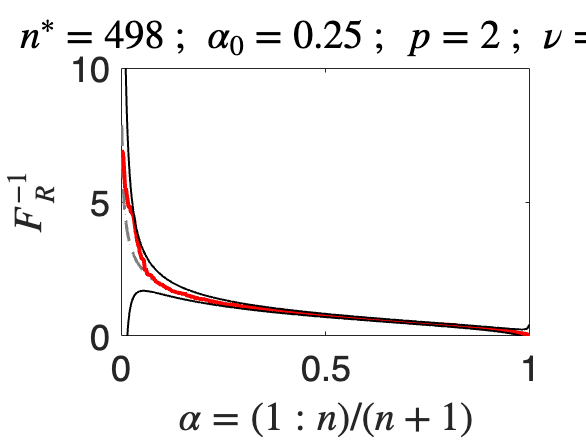

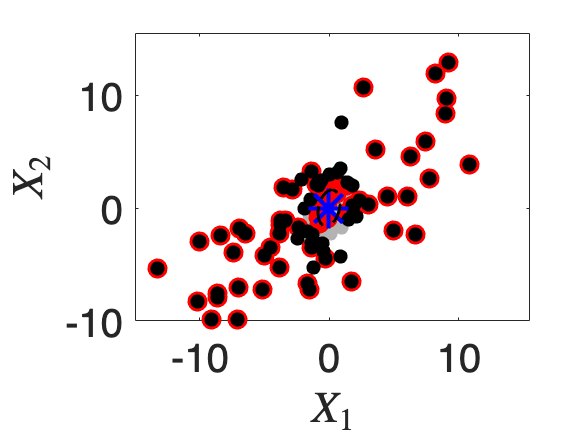

% out1 = [ds_path filesep 'outliers_Grass_nu_' num2str(Grass_nu_hat) '_epsilon_' num2str(Grass_epsilon_hat*100)];
% csvwrite([out1 '.txt'], Grass_outliers);

% Apply algorithm 3 to DS2: Returns

dsfile = [ds_path filesep dsfile2];
X2     = load(dsfile);
n2     = size(X2,1);
Xlabels2 = zeros(n2,1);
Xlabels2(n2-60+1:end) = 1;
alpha02 = 0.25;
[Returns_epsilon_hat, Returns_nu_hat, Returns_outliers, ...
    Returns_TPR, Returns_FPR, Returns_FNR] = algorithm3(X2,Xlabels2,alpha02);

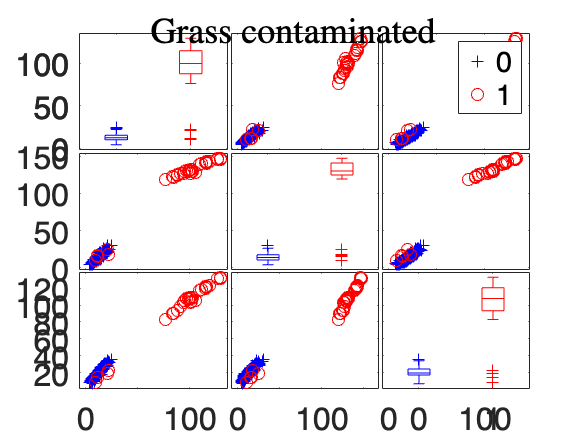

% out2 = [ds_path filesep 'outliers_Returns_nu_' num2str(Returns_nu_hat) '_epsilon_' num2str(Returns_epsilon_hat*100)];
% csvwrite([out2 '.txt'], Returns_outliers);


% Scatterplot matrix of DS1

outliers1 = zeros(size(X1,1),1);
outliers1(Grass_outliers,1) = 1;
figure;
[H1,AX1,BigAx1] = spmplot(X1,'group', outliers1,'dispopt','box','tag','Grass');
sgtitle('Grass contaminated','FontSize',18,'Interpreter','Latex');
set(AX1,'FontSize',16);

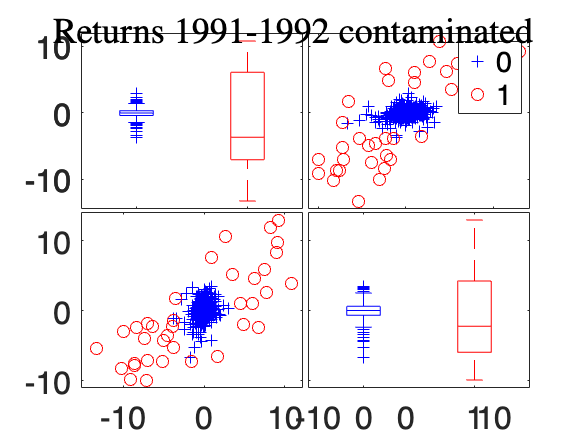

% saveas(BigAx1,[ds_path filesep 'grass.fig'],'fig');
% saveas(BigAx1,[ds_path filesep 'grass.eps'],'epsc');

% Scatterplot matrix of DS2

outliers2 = zeros(size(X2,1),1);
outliers2(Returns_outliers) = 1;
figure;
[H2,AX2,BigAx2] = spmplot(X2,'group', outliers2,'dispopt','box','tag','Returns');
sgtitle('Returns 1991-1992 contaminated','FontSize',18,'Interpreter','Latex');
set(AX2,'FontSize',16);

% saveas(BigAx2,[ds_path filesep 'returns.fig'],'fig');
% saveas(BigAx2,[ds_path filesep 'returns.eps'],'epsc');

% Performances of Algorithm 3 on the two datasets
disp(['Grass: nu = ' num2str(Grass_nu_hat) ' ; epsilon = ' num2str(Grass_epsilon_hat)]);

Grass: nu = 8 ; epsilon = 0.090909


disp(['   TPR: ' num2str(Grass_TPR)]);

   TPR: 1


disp(['   FPR: ' num2str(Grass_FPR)]);

   FPR: 0.016667


disp(['   FNR: ' num2str(Grass_FNR)]);

   FNR: 0



disp(['Returns: nu = ' num2str(Returns_nu_hat) ' ; epsilon = ' num2str(Returns_epsilon_hat)]);

Returns: nu = 3 ; epsilon = 0.042308


disp(['   TPR: ' num2str(Returns_TPR)]);

   TPR: 0.58333


disp(['   FPR: ' num2str(Returns_FPR)]);

   FPR: 0.0021739


disp(['   FNR: ' num2str(Returns_FNR)]);

   FNR: 0.41667
